%% Classify-X: Object Classification using Mobile Camera
% Classifies 3 images using two pretrained neural networks:
% GoogLeNet and SqueezeNet

## Connect to MATLAB Mobile

clear m;
m = mobiledev;
clear cam;
cam = camera(m,'back');

%% Load pretrained neural networks
[net1,classNames1] = imagePretrainedNetwork("googlenet");
[net2,classNames2] = imagePretrainedNetwork("squeezenet");

Capture Image 1 of 3


Image 1 Classification Results:


GoogLeNet  : water bottle


SqueezeNet : water bottle


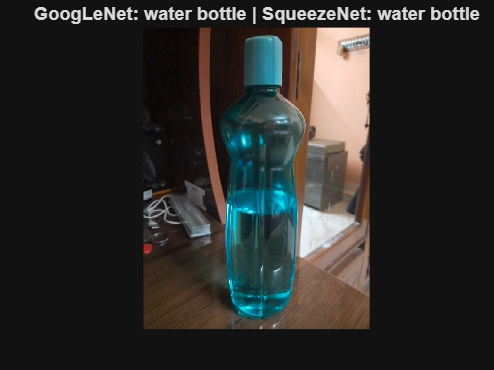

Capture Image 2 of 3


Image 2 Classification Results:


GoogLeNet  : screwdriver


SqueezeNet : spindle


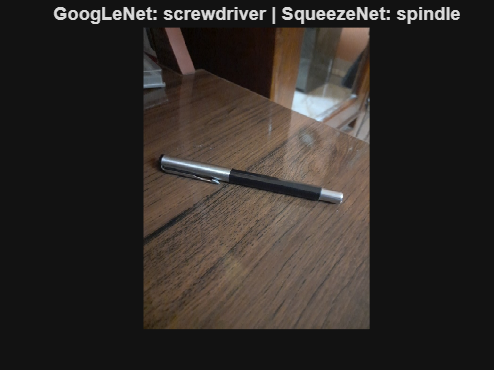

Capture Image 3 of 3


Image 3 Classification Results:


GoogLeNet  : modem


SqueezeNet : mouse


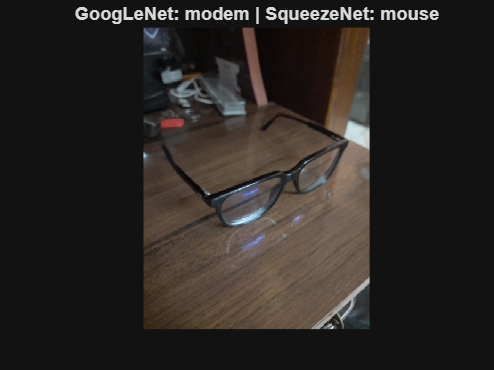

%% Classify 3 images
for i = 1:3

    % Capture image from mobile camera
    fprintf("\n========================================\n");
    fprintf("Capture Image %d of 3\n",i);
    fprintf("========================================\n");

    img = snapshot(cam,'manual');

    % Display captured image
    figure;
    imshow(img);
    title("Captured Image " + i);

    %% Classify using GoogLeNet
    inputSize1 = net1.Layers(1).InputSize;

    img1 = imresize(img,inputSize1(1:2));
    img1 = single(img1);

    scores1 = predict(net1,img1);

    label1 = scores2label(scores1,classNames1);

    %% Classify using SqueezeNet
    inputSize2 = net2.Layers(1).InputSize;

    img2 = imresize(img,inputSize2(1:2));
    img2 = single(img2);

    scores2 = predict(net2,img2);

    label2 = scores2label(scores2,classNames2);


    %% Display classification results
    fprintf("Image %d Classification Results:\n",i);
    fprintf("GoogLeNet  : %s\n",string(label1));
    fprintf("SqueezeNet : %s\n",string(label2));

    title("GoogLeNet: " + string(label1) + ...
        " | SqueezeNet: " + string(label2));

end